# Cortical Distance Analysis

## Fig 4D: Cortical Distance Measurements

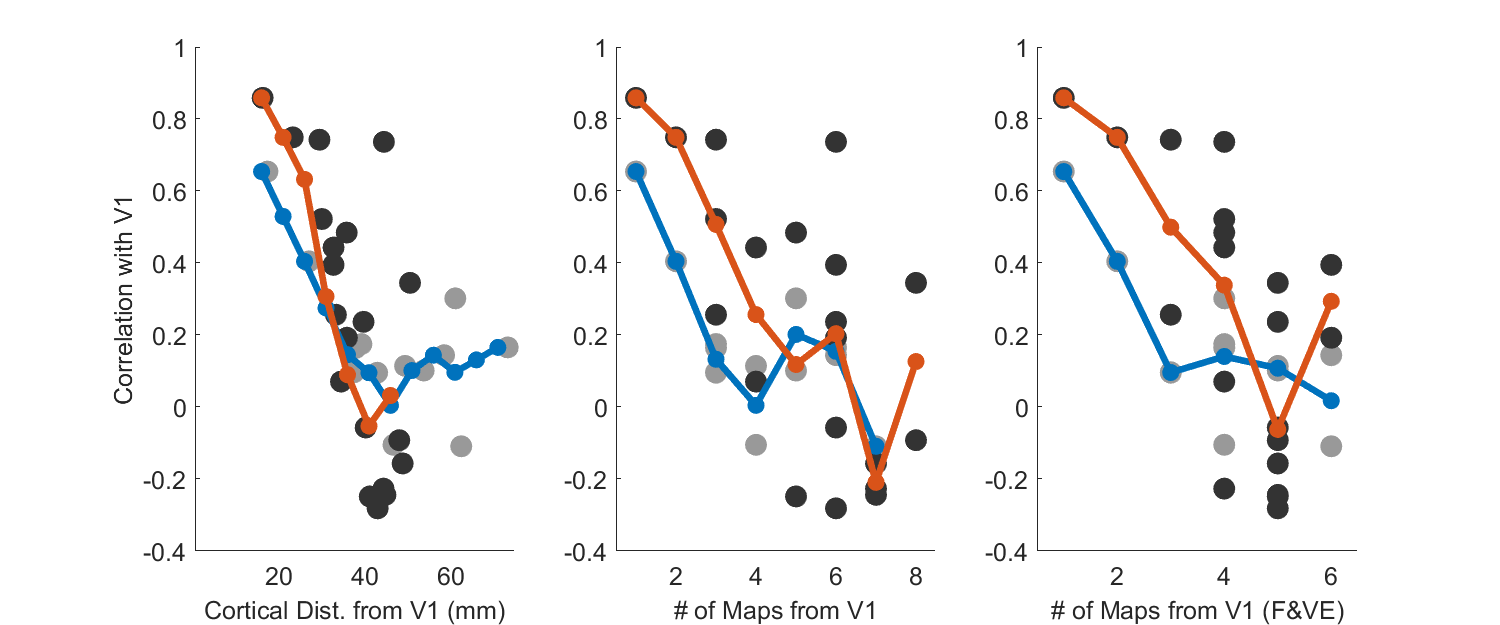

addpath(genpath('matlabfunctions'))
humans=load('Humans/alldata.mat');
monks=load('Monks/alldata.mat');

monks_cortdist=load('Monks/intermediate_files');
humans_cortdist=load('Humans/intermediate_files');
meanmonks_cortdist_rh=nanmean(monks_cortdist.avgdist_allsubjs_rh,2);
meanhumans_cortdist_rh=nanmean(humans_cortdist.avgdist_allsubjs_rh,2);
meanmonks_cortdist_lh=nanmean(monks_cortdist.avgdist_allsubjs_lh,2);
meanhumans_cortdist_lh=nanmean(humans_cortdist.avgdist_allsubjs_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

meanmonks_cortdist1234=[meanmonks_cortdist_lh1234+meanmonks_cortdist_lh1234]/2;

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=[meanhumans_cortdist_rh(1)+meanhumans_cortdist_rh(2)];
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];
meanhumans_cortdist_rh1234(11) = [];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=[meanhumans_cortdist_lh(1)+meanhumans_cortdist_lh(2)];
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];
meanhumans_cortdist_lh1234(11) = [];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

human_labels =          {'V1', 'V2', 'V3','hV4','VO1','VO2','PHC1','PHC2', 'V3A','V3B','LO1','LO2','TO1','TO2'}; 
human_areadistfromV1=    [0,     1,    2,   3,    4,   5,     6,      7,     3,    3,   3,    4,    5,    6];
human_fellemanhierarchy=  [1,    2,    3,   5,    6,    6,    7,      7,     4,    4,   5,    5,    5,    5]-1;

monk_labels =           {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
monk_areadistfromV1=      [0,    1,    2,   3,   4,   5,     6,    6,      6,      6,    3,    3,    4,    5,     6,     7,     8,     6,   7,    8,   7];
monk_fellemanhierarchy=   [1,    2,    3,   5,   5,   6,     6,    6,      7,      7,    4,    4,    5,     5,    6,     6,     6,     5,   6,    6,   5]-1;

monks_allareas=monks.V1_cat_corr1234;
humans_allareas=humans.V1_cat_corr1234;
humans_allareas(11) = [];

for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));   
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    monk_meanhierarchydist(x)=nanmean(monks_allareas(monk_fellemanhierarchy==x));
    human_meanhierarchydist(x)=nanmean(humans_allareas(human_fellemanhierarchy==x));   
end

stepsize=5;
maxrange=80;
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
human_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 80
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(5)=[human_meancortdist(4)+human_meancortdist(6)]/2;
human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 75])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Correlation with V1','fontsize',15)

subplot(1,3,2)
hold on
plot(human_areadistfromV1(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(monk_areadistfromV1(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(human_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])

box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
plot(human_fellemanhierarchy(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(monk_fellemanhierarchy(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(human_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)

## Plot distance metrics vs size relative to v1

temp_human = surfacearea_bothhemis_human(1:end-9,:);
t_human = [];
t_human(1,:) = temp_human(1,:) + temp_human(2,:);
t_human(2,:) = temp_human(3,:) + temp_human(4,:);
t_human(3,:) = temp_human(5,:) + temp_human(6,:);
t_human = [t_human(1,:);t_human(2,:);t_human(3,:);temp_human(7:end,:)];

monks_allareas=v_monkey./v_monkey(1,:);

Unrecognized function or variable 'v_monkey'.

monks_allareas = mean(monks_allareas,2,'omitnan');
humans_allareas=t_human./t_human(1,:);
humans_allareas = mean(humans_allareas,2,'omitnan');

for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));   
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    monk_meanhierarchydist(x)=nanmean(monks_allareas(monk_fellemanhierarchy==x));
    human_meanhierarchydist(x)=nanmean(humans_allareas(human_fellemanhierarchy==x));   
end

stepsize=5;
maxrange=80;
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
human_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 80
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(5)=[human_meancortdist(4)+human_meancortdist(6)]/2;
human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end,:),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end,:),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(1:stepsize:maxrange,human_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(1:stepsize:maxrange,monk_meancortdist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 75])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Area Size / V1 Size','fontsize',15)

subplot(1,3,2)
hold on
plot(human_areadistfromV1(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(monk_areadistfromV1(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(human_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanareadist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])

box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
plot(human_fellemanhierarchy(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',45)
plot(monk_fellemanhierarchy(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',45) 
plot(human_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0 0.4470 0.7410])
plot(monk_meanhierarchydist,'.-','MarkerSize',35,'LineWidth',4,'Color',[0.8500 0.3250 0.0980])
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
ax.FontSize = 15;
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)